Question3)

-audioread: read name_flies - > put data in Y and X and 

also take away a sample frequency of them

[y1,Fs1] = audioread('piano_C_sharp.mp3');
[y2,Fs2] = audioread('piano_G.mp3');

-fourier transform:

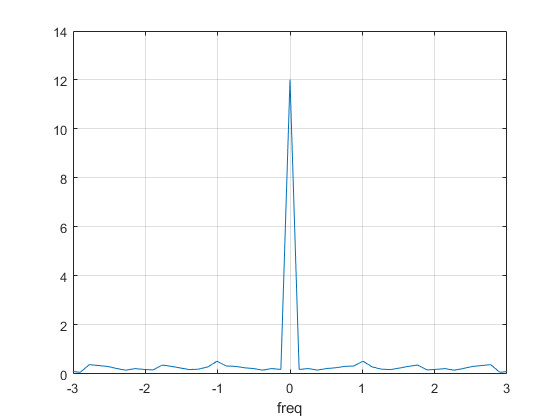

%y1
n= length(y1);
fFft=(-n/2:n/2-1)*(Fs1/n);
yFft=fft(y1);
yFftshift=fftshift(yFft);
plot(fFft,abs(yFftshift))
xlabel("freq")
xlim([-3,3])
grid on

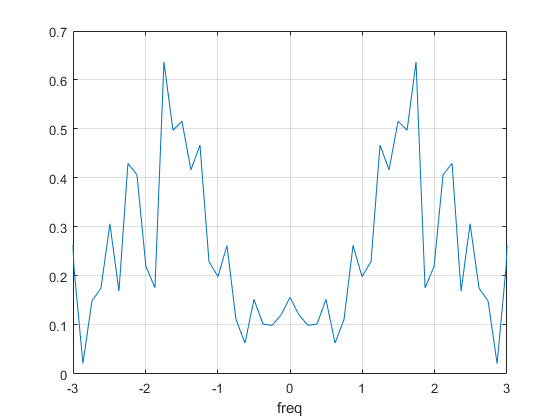

%y2
n= length(y2);
fFft=(-n/2:n/2-1)*(Fs2/n);
yFft=fft(y2);
yFftshift=fftshift(yFft);
plot(fFft,abs(yFftshift))
xlabel("freq")
xlim([-3,3])
grid on

-sound:

%overlap
sound(y1,Fs1);
sound(y2,Fs2);
pause(2.5) 
%non-overlap
pause(2.5)
sound(y1,Fs1);
pause(2.5) 
sound(y2,Fs2);
